##                                                                                                                                                                                                                General code information.

This code was written and adjusted by Rachel N. Gaines and James J. Griebler.

Future users can direct questions to Rachel at rngaines29@gmail.com, cc'ing Jimmy at jamesgriebler8@gmail.com. Please put "[HPLC Data Analysis Code]" in the subject line.

## What you will need in your MATLAB path to run this code.

- peakfitRNG.m

- findpeaksRNG.m

- (if you get errors) ipf.m from Prof. Tom O'Haver

## What this code does.

Allows you to choose:

- Whether to use a pressure-time calibration that will identify the drop in pressure at a particular run time, and the corresponding shift in your peaks of interest.

- The tolerance for searching for a particular peak (how much "wiggle room" your code has for identifying a peak) & the tolerance for labeling peaks (typically the label tolerance and search tolerance are the same.)

- How you add your files (copy as path - paste OR clicking).

- How to calculate your baseline (selecting a baseline shape AND from where to interpolate it.)

- The shape of each peak (what percent Gaussian/Lorentzian AND how wide they are.)

- Residual limits (how to view the residuals AND what the limit, in %, is.)

- Height limits (the minimum height under which MATLAB will not assign a peak).

- Whether or not to (1) analyze data from different detectors; (2) show each analyzed plot; (3) export the plot to an Origin-readable file.

- The times at which MATLAB will divide the data (best if you want to ignore certain sections of data, or if certain sections of data are of very different heights.)

- The time at which your data starts (typically this is 0).

## Where are my results?!?

Two places!

1 - in the "[filename]_PeakInfo.mat" variable in the folder in which your original text files are. This gives you peak locations and areas for individual files.

2 - In the exportData cell in the workspace. The first column is the name of the data; clicking on the same row in the second column will give you the data output. This gives you peak names, locations, and areas for all files. 

### Close open files and clear workspace.

close all;
clear all;

### Set your working directory.

% cd 'C:\Users\rngai\OneDrive - University of Illinois - Urbana\Research\2-Data';

### Add your files. 

Check "click files" if you would rather manually select files one-by-one once the code runs. Otherwise, select all your files, right-click and select "copy as path," and paste them in between the brackets in the *other_experimental_files* variable.

%select if you want to choose files by clicking
%if unchecked, add files to "other_experimental_files"
click_files=false;

first_experimental_file = "C:\Users\rngai\OneDrive - University of Illinois - Urbana\Personal Website\Resources\Code\HPLC\SampleDataFile_Solution.txt";

if click_files==false
    %type here if you dont want to repeadly click
other_experimental_files = [
% EXAMPLE:
%"C:\Users\Rachel\HPLC\SampleDataFile_Experiment.txt"
];
else
     
    temp_names_cell= openmultiplefiles();
    try
        cell2mat(temp_names_cell)
        other_experimental_files=separateNames(temp_names_cell);
        clear temp_names_cell;
    catch

        other_experimental_files=convertCharsToStrings(temp_names_cell);
    end  
end

### Choose how to divide your data for each detector, and whether to analyze the data for each detector.

*start_time* is the x-value at which your data starts. For HPLC data, this is typically zero.

*XX_splits* is where you want MATLAB to "cut off" your data. For example, *A1_splits = [4, 9.5]* divides your spectrum into three splits: 0 to 4 minutes, 4.01 to 9.5 minutes, and 9.51 to end minutes. This is most useful to cut off certain parts of your data or if different sections of your data require different analysis parameters (different size/shape of peaks, for example.)

*analyze_XX* is whether or not MATLAB should analyze data from a particular detector.

*analyze_split_data* indicates whether to analyze the data in splits or as a whole. Typically, if you're splitting your data, you will want this checked.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   
%make sure that your split numbers are numbers that you can find in your source data! Else the code will throw errors.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%  

start_time = 0;

%A1
A1_splits = [16];

%A2
A2_splits = [7];

%RID
RID_splits = [12,14.5];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   

%please only analyze one detector at a time!!
analyze_A1 = true; % if checked, analyzes data from detector A1
analyze_A2 = false; % if checked, analyzes data from detector A2
analyze_RID = false; % if checked, analyzes data from RID detector

analyze_split_data=true; % if checked: run analysis on the split data separately (e.g., runs analysis on 0 to 9.5 min and then runs analysis on 9.51 to 18 min)

### Choose your baseline window and type. This will depend on your data - YOU MUST INSPECT YOUR DATA.

Default values: 

- *baseline_window*: start

- *baseline_type*: N/A, must be entered

*baseline_window* can tolerate differences between it and the number of splits in the data. 

If the data is not split at all, the code will interpolate baselines according to the first element listed in *baseline_window*. 

If there are MORE splits than strings (e.g., you enter 2 splits - which is 3 sections of data - into *A1_splits* and only 2 strings into *baseline_window*), the code will default to a value of "start" for baseline interpolation. 

If there are LESS splits than strings (e.g., you enter 2 splits - 3 sections of data - into *A1_splits* and have 4 strings in *baseline_window*), the code will ignore the last string.

The code is agnostic to capitalization. "Start," "START," and "start" will all work.

*baseline_window* identifies how to interpolate the baseline data and adjust it for proper analysis. "start" interpolates based on the first 3% of the data in the split; "end" interpolates based on the last 3% of the data in the split, "both" interpolates based on both the first and last 3% of the data.

*baseline_type *identifies the type of baseline in your data. YOU MUST INSPECT YOUR DATA. 0=no baseline; 1 = linear baseline; 2 = quadratic baseline.

choose_baseline_window=true; % if checked, fill "baseline window" with strings. Otherwise, default value is "start"

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    
%A1:
    baseline_window=["start","both"];

%A2
    % baseline_window=["both","both"];

%RID:
    % baseline_window=["both","both","both"];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    

baseline_type = 2;

### Choose your peak shape and width for each data split.

*blends* is the % of your peak that is Gaussian in shape. For example, 70% means your peak is 70% Gaussian and 30% Lorentzian in shape.

*widths* is the width of your peaks. This sometimes changes in a spectrum - YOU MUST INSPECT YOUR DATA.

Similar to *baseline_window*, both *blends* and *widths* will tolerate variations in peak position up to the tolerance you specify in *tol*.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    
%A1:
    blends=[100,100,100];
    widths=[0.25,0.27,0.27];

%A2:
    % blends=[100,100];
    % widths=[0.30,0.30];

%RID:
    % blends=[100,100,100];
    % widths=[0.25,0.30,0.30];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
%leave this as-is
if analyze_A1==true
    [width_matrix,blend]=AddWidthsAndBlends(numel(A1_splits),widths,blends,analyze_split_data); % don't worry about this
elseif analyze_A2==true
    [width_matrix,blend]=AddWidthsAndBlends(numel(A2_splits),widths,blends,analyze_split_data); % don't worry about this
elseif analyze_RID==true
    [width_matrix,blend]=AddWidthsAndBlends(numel(RID_splits),widths,blends,analyze_split_data); % don't worry about this
end

### Choose your peak analysis methods.

*usePressureTimeCorrelation* is most useful for columns that are old or show shifts in peak position with pressure/time variation.

*percentResidual* changes the plotting in each spectrum from an absolute value to a percent of the maximum height of the spectra.

*maxResidual* indicates the largest percent residual you are willing to accept for your data. This is where the third (and fourth, fifth, etc.) columns in the *exportData* variable come in. If your first split (say, 0 to 4 min, as in the example above) has a residual beyond the value of *maxResidual*, an error message will print in the third column of the same row (right next to the cell containing the data.) If your second split has the same issue, an error message will print in the fourth column of the same row, and so on and so forth. These indicate splits you will need to integrate by hand (if you care about the data.) More information on integration "by hand" can be found at the end of the user-defined section of data.

*tol* tells MATLAB the maximum tolerance, in x-value units (usually minutes for HPLC data), in which you expect to find a certain peak. This is essentially the "search window" for a particular peak.

*label_tol* is the maximum tolerance, in x-value units, in which you will allow MATLAB to label a certain peak. Typically this is the same value as *tol*.

*height_threshold* is the minimum height of a peak, in y-value units (mAU for HPLC data). Any peak shorter than this height will not be evaluated by MATLAB.

usePressureTimeCorrelation=false; % if checked: uses pressure-time curve to identify peak positions

percentResidual=true; % if checked: plots residual as a percentage of maximum height of spectra

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 

% define maximum percent residual you are willing to accept (on a scale of
% zero to one hundred; inputting 100 = 100% of maximum height is the maximum height of your residual. Recommended setting is 30 or less.)
maxResidual = 20;

tol = 0.10; % min

label_tol = tol; %min

height_threshold = 200; % if you choose to not use a baseline, you will have to change the height threshold for each split

### Define your desired outputs.

plots=true; % if checked: prints a MATLAB-generated plot for each split
export = true; % if checked: exports the fit of the spectrum to a .mat file (that is importable to origin)

### Coming soon! (This is not functional right now, please just leave it checked..) Define if you want to use a calibration curve to calculate "real world" values from your data.

calibrationCurve=true;

### ~~~~~~~~

### If my code tells me to "inspect this data," I should... (or, how to do analysis by hand):

- Download ipf.m from Prof. Tom O'Haver's website.

- Navigate to the appropriate file folder on the left-hand "Current Folder" bar in MATLAB. You will want the files titled "[file name]_split_data.mat."

- Double-click on one of the files to open it. In the bottom of the "Current Folder" or in the "Workspace," you should see variables A1_split, A2_split, and RID_split. If you see those, you are using the right file.

- Open up the "Command Window" in MATLAB. It should show "load('yourfilepath') as its most recent command. If not, double-click on the file again.

- Type: ipf(XX_split{1,N}) where XX is the detector in which you are analyzing data, and N is the number of the split you're interested in. For example, if you want the first split of data (say 0 to 4 min) from detector A2, you would type *ipf(A2_split{1,1})*.

- In the popup window, ctrl-A to view the whole (split) spectrum. Double-check that you have the correct split. 

- Use the "t" key to select the appropriate baseline. This should be the same baseline that you are using for the looped data.

- Use the "~" or "`" key to select a Gaussian/Lorentzian blend as the peak shape (what this code uses). 

- Hit the number key corresponding to the number of peaks you are looking for.

- Hit the "c" key. Click once on each peak location. NOTE: there will not be any indication you have clicked on anything. However, after you click the number of times you enter in step 8, the fit will automatically run.

- After the fit runs, shift-X and type in the percent Gaussian (e.g., 70), then <enter>. 

- Click back into the popup window. 

- Use the "a" key to do coarse increase of the percent Gaussian and the "z" key to do coarse decreases. Shift-a and shift-z do fine increases/decreases. Adjust the fit until the R^2 and/or residual are acceptable. This should be close, but likely not exact, to the percent you are using for the looped data.

- Hit the "r" key. The fit results will print in the command window. If it prints out with 1.0e+03 * [your data], type *format shortG*, return to your plot, and hit the "r" key again.

- Copy and paste those results to your favorite graphing software.

- Type *close all* in the workspace and hit enter.

- Type *clear all* in the workspace and hit enter.

- Repeat for as many data files as you need!

Rachel's typical uses, written here for easy copy-pasting:

ipf(A1_split{1,2})

ipf(A1_split{1,3})

~~~~~~~~

### This code initializes variables and should not need to be changed. (Continue scrolling for the pressure-time equation and pressure-peak shift equations.)

if analyze_split_data==false
    height_threshold=2200;
end
baseline_percentage=3;

if analyze_A1==true
    baseline_window_auto=FindBaselineWindow(numel(A1_splits),choose_baseline_window,baseline_window,analyze_split_data);
elseif analyze_A2==true
baseline_window_auto=FindBaselineWindow(numel(A2_splits),choose_baseline_window,baseline_window,analyze_split_data);
elseif analyze_RID==true
    baseline_window_auto=FindBaselineWindow(numel(RID_splits),choose_baseline_window,baseline_window,analyze_split_data);
end

%initalize Variables
parameters=[analyze_A1,analyze_A2, analyze_RID,export,start_time];
splits={A1_splits,A2_splits,RID_splits};

baseline_info{1}=baseline_percentage;
experimental_files = [first_experimental_file; other_experimental_files]; % this line MUST go before initializing the num_data_files and other variables dependent on its size;
num_data_files=size(experimental_files,1);


[A1_split, A2_split, RID_split,detector_A1,detector_A2,detector_RID,...
    time,signal,baseline_subtracted_signal,FitResults,GOF,baseline,coeff,residual,xi,yi,time_since_first_test,...
    pressure,GEA_pp, GOA_pp,OA_pp,LA_pp,FA_pp,date_and_time]=...
    Initalize(experimental_files,num_data_files,A1_splits,usePressureTimeCorrelation);

if analyze_A1==true
residual_string = strings(num_data_files,numel(A1_splits)+1); % this line MUST go AFTER initializing num_data_files AND the initialize function (that initializes A1_splits)
elseif analyze_A2==true
    residual_string = strings(num_data_files,numel(A2_splits)+1);
elseif analyze_RID==true
    residual_string = strings(num_data_files,numel(RID_splits)+1);
end

### This code contains the pressure-time equation (line 124), the peak-shift equations (lines 125-130), the peak positions (line 131 if the user elects to use the pressure-time equation, line 135 if not) and the peak names (line 132 if the user elects to use the pressure-time equation, line 136 if not). Those lines can be adjusted to your particular circumstances. Other bits of code should not need to be adjusted.

for x = 1:1:num_data_files
    % split data file into requested time ranges
    [A1_split{x},A2_split{x},RID_split{x},...
        detector_A1{x},detector_A2{x},detector_RID{x},date_and_time(x)]=...
        HPLC_Separation_IP(experimental_files,parameters,splits,x);
    % if user elects to initialize the use of the pressure-time equation, use the following pressure-time equation to calculate peak positions
end

for x = 1:1:num_data_files
    if usePressureTimeCorrelation == true
        time_since_first_test(x) = (date_and_time(x) - date_and_time(1)) * (86400/60); % convert from excel time to minutes
        pressure(x,1) = -0.0111 * (time_since_first_test(x,1) + 9) + 726.07;   % r^2 = 0.9843
        GEA_pp(x,1) = -0.0111 * pressure(x,1) + 18.677; % r^2 = 0.984
        GOA_pp(x,1) = -0.0134 * pressure(x,1) + 21.718; % r^2 = 0.937
        OA_pp(x,1) = -0.0035 * pressure(x,1) + 9.0431;  % r^2 = 0.9357
        FA_pp(x,1) = -0.0085 * pressure(x,1) + 19.622;  % r^2 = 0.9679
        LA_pp(x,1) = -0.0083 * pressure(x,1) + 18.366;  % r^2 = 0.9159
        GLY_pp(x,1) = 12.73; % does not change over the course of experiments
        peakpositions(:,x) = [OA_pp(x,1), GEA_pp(x,1), GOA_pp(x,1), LA_pp(x,1), GLY_pp(x,1), FA_pp(x,1), 12.95, 6.33, 5.95, 5.75, 5.55]'; 
        peaknames(:,x)=["OA" "GEA" "GOA" "LA" "GLY" "FA" "DHA"]; 
    else

% if user does NOT elect to initialize the use of the pressure-time equation, use the following locations as first guesses for peak locations
        
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
%A1
       % START HERE! 
        peakpositions(:,x)=[10.45, 11.8, 12.2, 12.7, 13.0, 13.3];
        peaknames(:,x)=["GEA" "GOA" "LA" "GLY" "DHA" "FA"];

        % use small adjustments as needed to get the proper integration.
        % before OA - solvent peak
        % 6.15 (OA)
        % 10.45 (GEA)
        % 11.8 (GOA)
        % 12.2 (LA)
        % 12.6 - 12.8 (GLY, if visible)
        % 12.9 - 13.15 (DHA)
        % 13.2 - 13.45 (FA)

%RID (Det. B)
    % peakpositions(:,x)=[11.3, 13.4];
    % peaknames(:,x)=["GEA" "FA"];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%                
        
    end 
end


### The rest of this code should not need to be adjusted.

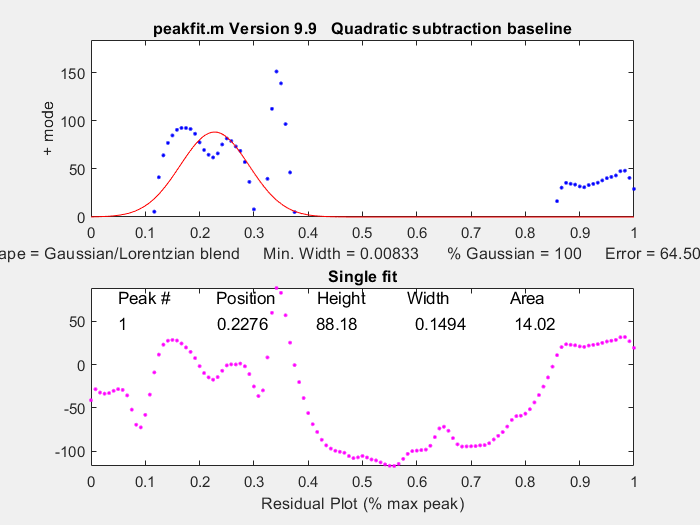

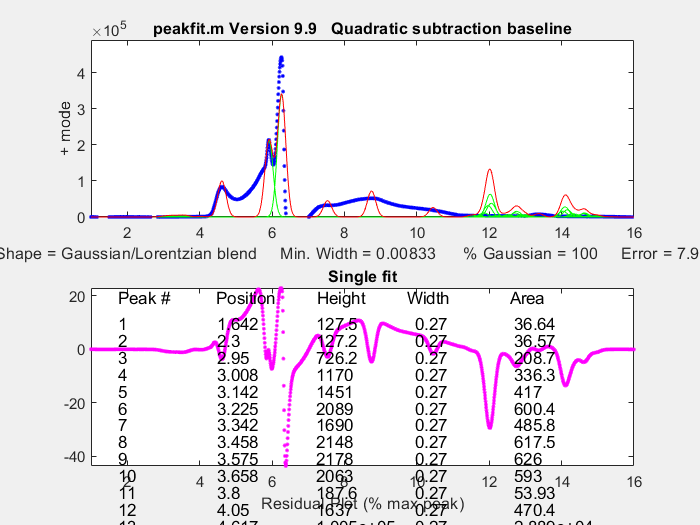

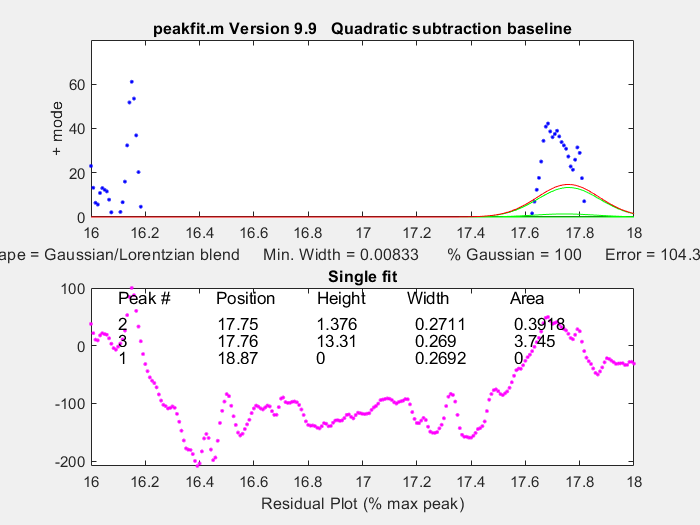

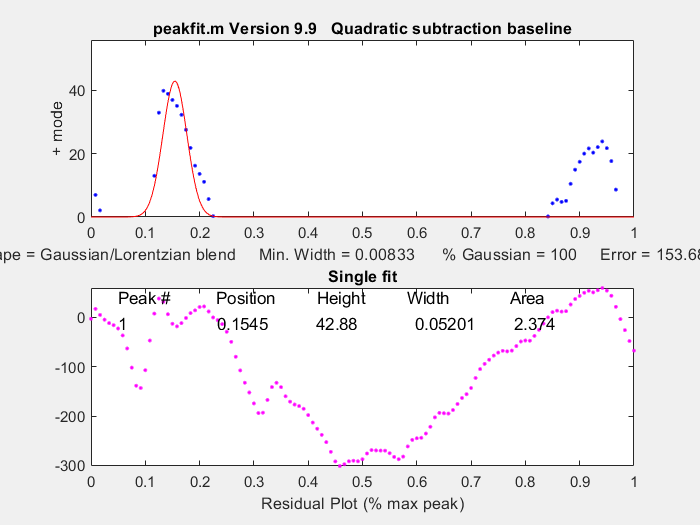

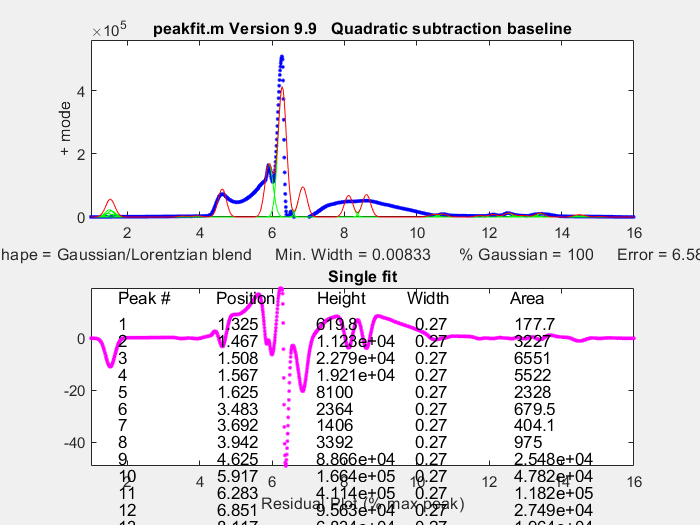

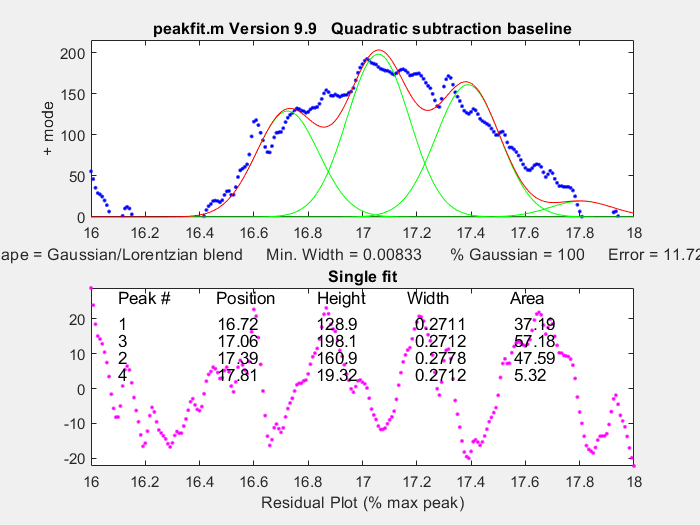

for x = 1:1:num_data_files
    if analyze_split_data==true
        % if you want to analyze the data in chunks specified by A1_splits, (e.g., 0 to 9.5 min and 9.51 to 18 min):
        if analyze_A1==true
            whichSetToUse=A1_split;
        elseif analyze_A2==true
            whichSetToUse=A2_split;
        elseif analyze_RID==true
            whichSetToUse=RID_split;
        end
        for i=1:1:numel(whichSetToUse{1})
            baseline_info{2}=baseline_window_auto(i);

            time{x}{i} = whichSetToUse{x}{i}(:,1);
            signal{x}{i} = whichSetToUse{x}{i}(:,2);

            baseline_subtracted_signal{x}{i}=LinearBaselineCorrection(baseline_info,signal{x}{i}); % fits a line to the first and last 10% of data IN THE SPLIT (not all the data) and subtracts that from the raw spectrum
            % (This essentially baseline-shifts your data to zero, makes analysis easier)
            % This is a first-pass to find peak positions that you have NOT already specified in the peakpositions vector.
            % If you have NOT specified a position, and the peak you want is smaller in magnitude than the variable "height_threshold," make this number smaller.
            [FitResults{x}{i},GOF{x}{i},baseline{x}{i},...
                coeff{x}{i},residual{x}{i},xi{x}{i},yi{x}{i}]=...
                FindAndFitPeaks(time{x}{i},signal{x}{i},baseline_subtracted_signal{x}{i},...
                peakpositions(:,x),tol,height_threshold,width_matrix(i),blend(i),baseline_info,plots,percentResidual,baseline_type);
        
                if any(abs(residual{x}{i}(1,:)) > maxResidual)
                    residual_string(x,i) = "Inspect this spectrum. Residual in split beginning at " + whichSetToUse{x}{i}(1,1) + " min > " + maxResidual + "% of total height, please manually recalculate if these are important.";
                
                end
        
        end
        if numel(whichSetToUse{1})>1
            NumberOfPeaksFound(x)=0;
            for i=1:1:numel(whichSetToUse{1})
                NumberOfPeaksFound(x)=NumberOfPeaksFound(x)+numel(FitResults{x}{i}(:,1));

            end
            for i=1:1:numel(whichSetToUse{1})
                if i==1
                    FitResultsPerFile{x}=FitResults{x}{i}(:,:);
                else
                    FitResultsPerFile{x}=[FitResultsPerFile{x};FitResults{x}{i}(:,:)];
                end

            end


        end
    else %if analyize_split_peak=false
        baseline_info{2}=baseline_window_auto(1);
        time{x} = detector_A1{x}(:,1);
        signal{x} = detector_A1{x}(:,2);
        baseline_subtracted_signal{x}=LinearBaselineCorrection(baseline_info,signal{x});

        [FitResultsPerFile{x},GOF{x},baseline{x},...
            coeff{x},residual{x},xi{x},yi{x}]=...
            FindAndFitPeaks(time{x},signal{x},baseline_subtracted_signal{x},...
            peakpositions(:,x),tol,height_threshold,width,blend,baseline_info,plots,percentResidual,baseline_type);
    end


FitResultsOneFile=FitResultsPerFile{x};
String=["Peak Number" "Position" "Height" "Width" "Area"];

if export==1 %if exporting of waveform and avgDynamicModuli data is desired
    save_filename2=[experimental_files{x},'_peakInfo.mat']; %define output filename
    save(save_filename2,'FitResultsOneFile') %save waveform and avgDynamicModuli data as structure
    clear FitResultsOneFile
end

end


disp("tests complete " + x + " out of " + num_data_files)

tests complete 2 out of 2





for x=1:1:num_data_files

    holdPositions=FitResultsPerFile{x}(:,2);
    peakNamesForTable=strings(numel(holdPositions),1);

    for i = 1:numel(holdPositions)
        for j=1:size(peaknames,1)

            if abs(holdPositions(i) - peakpositions(j,x)) < label_tol
                peakNamesForTable(i,1)=peaknames(j);

            end
        end
    end
    peakNamesForTable;
    charHold{x}=convertStringsToChars(experimental_files(x));
    exportData{x,1}=charHold{x}(end-18:end);
    % numel(peakNamesForTable)
    % numel(FitResultsPerFile{x}(:,2))
    % numel(FitResultsPerFile{x}(:,5))
    exportData{x,2}=table(peakNamesForTable,FitResultsPerFile{x}(:,2),FitResultsPerFile{x}(:,5),'VariableNames',["Peak Name" "Peak Position" "Peak Area"]);

    for j = 1:1:(length(whichSetToUse{1}))
        exportData{x,j+2} = residual_string(x,j);
    end

    clear holdPositions
    clear peakNamesForTable

end

%if calibrationCurve==true, go through each data set and pull out all the
%areas for that particular thing
%user input concentration
%fit the data and give the fit, save the results

## Below this is all functions required to run this code except findpeaksRNG.m and peakfitRNG.m. DO NOT CHANGE THESE.

function file_names_cell=...
    openmultiplefiles()
file_names_cell=uigetfile('*.txt','MultiSelect','on');
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function file_names_matrix=...
    separateNames(file_names_cell)
file_names_long_char_list=cell2mat(file_names_cell);
file_names_long_string=convertCharsToStrings(file_names_long_char_list);
file_names_matrix=split(file_names_long_string,".txt");
file_names_matrix(end)=[];
for i=1:1:numel(file_names_matrix)
    file_names_matrix(i)=append(file_names_matrix(i),".txt");
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [width_matrix,blend_matrix]=...
    AddWidthsAndBlends(split_size,user_widths,user_blends,analyze_split_data)
if analyze_split_data==true
blend_matrix=zeros(split_size+1,1);
width_matrix=zeros(split_size+1,1);
blend_matrix(:)=50;
width_matrix(:)=0.25;

for i=1:1:split_size+1
    if numel(user_widths)<split_size+1
        if analyze_split_data == true && i<=numel(user_widths)

            width_matrix(i) =user_widths(i);
            blend_matrix(i)=user_blends(i);
            % if you wish to analyze your data as a full spectrum:
        end
    elseif numel(user_widths)>split_size+1

        blend_matrix=zeros(numel(user_blends),1);
        width_matrix=zeros(numel(user_widths),1);
        for i=1:1:numel(user_widths)
            blend_matrix(i)=user_blends(i);
            width_matrix(i)=user_widths(i);
        end
    elseif numel(user_widths)==split_size+1
        clear blend_matrix
        clear width_matrix
        blend_matrix=user_blends;
        width_matrix=user_widths;
    end
end
else 
    if numel(user_blends)>0
        blend_matrix=user_blends(1);
    else
        blend_matrix=50;
    end
    if numel(user_widths)>0
        width_matrix=user_widths(1);
    else
    width_matrix=0.25;
    end
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function baseline_window_auto=...
    FindBaselineWindow(split_size,choose_baseline_window,baseline_window,analyze_split_data)
if analyze_split_data==true
    baseline_window_auto=strings(split_size+1,1);
baseline_window_auto(:)="start";
if choose_baseline_window==false
    if split_size+1==2
        baseline_window_auto=["both","start"];
    else
        baseline_window_auto(:)="start";
    end
else
    if numel(baseline_window)==split_size+1
        baseline_window_auto=baseline_window;
    elseif numel(baseline_window)>split_size+1
        for i=1:1:split_size+1

            baseline_window_auto(i)=baseline_window(i);
        end
    elseif numel(baseline_window)<split_size+1
          for i=1:1:numel(baseline_window)

            baseline_window_auto(i)=baseline_window(i);
        end

    end
end
else
    baseline_window_auto=baseline_window(1);
end
for i=1:1:numel(baseline_window_auto)
    if (baseline_window_auto(i)~="both") && (baseline_window_auto(i)~="start") &&(baseline_window_auto(i)~="end") &&...
            (baseline_window_auto(i)~="BOTH") && (baseline_window_auto(i)~="START") &&(baseline_window_auto(i)~="END") &&...
            (baseline_window_auto(i)~="Both") && (baseline_window_auto(i)~="Start") &&(baseline_window_auto(i)~="End")
        baseline_window_auto(i)="start";
    end
    if (baseline_window_auto(i)=="Start") ||(baseline_window_auto(i)=="START")
        baseline_window_auto(i)="start";
    end
    if (baseline_window_auto(i)=="End") ||(baseline_window_auto(i)=="END")
        baseline_window_auto(i)="end";
    end

end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function baseline_subtracted_signal =...
    LinearBaselineCorrection(baseline_info, signal)

baselinepercentage=baseline_info{1};
baseline_window=baseline_info{2};
baselinefraction=1/(baselinepercentage/100);
datasize=size(signal);
if datasize(1)<datasize(2),signal=signal';end
datasize=size(signal);
if datasize(2)==1 %  'signal' is a vector; Must be peakfit(Y-vector)
    X=1:length(signal); % Create an independent variable vector
    Y=signal;
else
    % 'signal' is a matrix. Must be peakfit(DataMatrix)
    X=signal(:,1); % Split matrix argument
    Y=signal(:,2);
end
X=reshape(X,1,length(X)); % Adjust X and Y vector shape to 1 x n (rather than n x 1)
Y=reshape(Y,1,length(Y));
% If necessary, flip the data vectors so that X increases
if X(1)>X(length(X))
    disp('X-axis flipped.')
    X=fliplr(X);
    Y=fliplr(Y);
end


n1=1;
n2=length(X);

xx=X(n1:n2);
yy=Y(n1:n2);
lxx=length(xx);
bkgsize=round(length(xx)/baselinefraction);
if bkgsize<2
    bkgsize=2;
end
XX1=xx(1:round(lxx/bkgsize));
XX2=xx((lxx-round(lxx/bkgsize))+1:lxx);
Y1=yy(1:(round(length(xx)/bkgsize)));
Y2=yy((lxx-round(lxx/bkgsize))+1:lxx);
if baseline_window=="start"
    bkgcoef=polyfit(XX1,Y1,1);  % Fit straight line to sub-group of points
elseif baseline_window=="end"
    bkgcoef=polyfit(XX2,Y2,1);
else
    bkgcoef=polyfit([XX1,XX2],[Y1,Y2],2);

end
bkg=polyval(bkgcoef,xx);
baseline_subtracted_signal=(yy-bkg)';

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [A1_split, A2_split, RID_split,detector_A1,detector_A2,detector_RID,...
    time,signal,baseline_subtracted_signal,FitResults,GOF,baseline,coeff,residual,xi,yi,time_since_first_test,...
    pressure,GEA_pp, GOA_pp,OA_pp,LA_pp,FA_pp,date_and_time]=...
    Initalize(experimental_files,num_data_files,A1_splits,usePressureTimeCorrelation)

A1_split=cell(size(experimental_files));
A2_split=cell(size(experimental_files));
RID_split=cell(size(experimental_files));
detector_A1=cell(size(experimental_files));
detector_A2=cell(size(experimental_files));
detector_RID=cell(size(experimental_files));

time=cell(num_data_files,1);
signal=cell(num_data_files,1);
baseline_subtracted_signal=cell(num_data_files,1);
FitResults=cell(num_data_files,1);
GOF=cell(num_data_files,1);
baseline=cell(num_data_files,1);
coeff=cell(num_data_files,1);
residual=cell(num_data_files,1);
xi=cell(num_data_files,1);
yi=cell(num_data_files,1);

for i=1:1:num_data_files
    time{i}=cell(numel(A1_splits)+1,1);
    signal{i}=cell(numel(A1_splits)+1,1);
    baseline_subtracted_signal{i}=cell(numel(A1_splits)+1,1);
    FitResults{i}=cell(numel(A1_splits)+1,1);
    GOF{i}=cell(numel(A1_splits)+1,1);
    baseline{i}=cell(numel(A1_splits)+1,1);
    coeff{i}=cell(numel(A1_splits)+1,1);
    residual{i}=cell(numel(A1_splits)+1,1);
    xi{i}=cell(numel(A1_splits)+1,1);
    yi{i}=cell(numel(A1_splits)+1,1);
end
if usePressureTimeCorrelation==true
    time_since_first_test = zeros(num_data_files,1);
    pressure = zeros(num_data_files,1);

    GEA_pp = zeros(num_data_files,1);
    GOA_pp=zeros(num_data_files,1);
    OA_pp =zeros(num_data_files,1);
    FA_pp=zeros(num_data_files,1);
    LA_pp=zeros(num_data_files,1);
    date_and_time=zeros(num_data_files,1);

else
    time_since_first_test=0;pressure=0;GEA_pp=0;GOA_pp=0;OA_pp=0;FA_pp=0;LA_pp=0;GLY_pp=0;date_and_time=0;
end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function[FitResults,GOF,baseline,coeff,residual,xi,yi]=...
    FindAndFitPeaks(time,signal,baseline_subtracted_signal,peakpositions,tol,height,width,...
    blend,baseline_info,plots,percentResidual,baseline_type)

baselinepercentage=baseline_info{1};
baselinefraction=1/(baselinepercentage/100);
desired_peaks = peakpositions(peakpositions > time(1,1)); % removes any peaks from the variable "peakpositions" that are less than the minimum of the time range of the split
desired_peaks = desired_peaks(desired_peaks < time(end,1)); % removes any peaks from the variable "peakpositions" that are greater than the maximum of the time range of the split
FoundPeaks=findpeaksRNG(time,baseline_subtracted_signal,0,height,0,1); % use the findpeaks.m function to find additional peaks in the baseline-subtracted signal that (1) may not be specified by "peakpositions" and (2) are greater than "height"
centers = FoundPeaks(:,2); % take the x-position (time) of those found peaks
centers_unique = RemoveCentersWithinTolerance(centers,tol); % removes any peaks within the set tolerance of each other (e.g., [13.8, 13.85, 13.95] -> [13.8, 13.95])

allpeakpositions = [centers_unique; desired_peaks(~any(abs(desired_peaks - centers_unique') <= tol, 2))];  % combines the variables "desired_peaks" (user-specified peak positions) and "centers_unique" (function-generated peak positions), removing any duplicates (i.e., removes one of the two values within tolerance of each other);
% "allpeakpositions" is used as a first-guess for the location of a
% peak in the peak fitting function
guess = zeros(2*numel(allpeakpositions)); % initializes the first-guess locations for the peak fitting function, along with the user-inputted peak width
for i = 1:1:numel(allpeakpositions)
    guess(2*i-1) = allpeakpositions(i);
    guess(2*i) = width;
end
residual_and_baseline=[percentResidual,baselinefraction];

[FitResults,GOF,baseline,coeff,residual,xi,yi]= peakfitRNG([time,signal],0,0,numel(allpeakpositions),13,blend,1,guess,baseline_type,0,plots,residual_and_baseline);

end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function centers_unique = ...
    RemoveCentersWithinTolerance(centers,tol)


centers_unique = centers;
for i = 1:numel(centers)-1
    if any(abs(centers_unique(i+1:end) - centers_unique(i)) > tol == 0.09)
        centers_unique(i) = NaN;
    end
end
centers_unique = centers_unique(~isnan(centers_unique));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [index,closestval]=val2ind(x,val)
% Returns the index and the value of the element of vector x that is closest to val
% If more than one element is equally close, returns vectors of indicies and values
% Tom O'Haver (toh@umd.edu) October 2006
% Examples: If x=[1 2 4 3 5 9 6 4 5 3 1], then val2ind(x,6)=7 and val2ind(x,5.1)=[5 9]
% [indices values]=val2ind(x,3.3) returns indices = [4 10] and values = [3 3]
dif=abs(x-val);
index=find((dif-min(dif))==0);
closestval=x(index);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [A1_split,A2_split,RID_split,detector_A1,detector_A2,detector_RID,date_and_time] =...
    HPLC_Separation_IP(experimental_files,parameters,splits,x)
%% DATA CLEANING AND IMPORTING %%


A1_splits=splits{1};
A2_splits=splits{2};
RID_splits=splits{3};
analyze_A1=parameters(1);
analyze_A2=parameters(2);
analyze_RID=parameters(3);
export=parameters(4);
start_time=parameters(5);
warning('off')

% pairing experimental and baseline files
% if size(baseline_files) ~= 0
% if mod(x-1,experiments_per_baseline) == 0
%     fname2 = convertStringsToChars(baseline_files(ceil(x/experiments_per_baseline)));
%     raw_text_file2 = readtable(fname2);
%     raw_data_matrix2 = table2array(raw_text_file2(data_start:end, 1:2));
% end
% end



% convert file name to characters, so we can modify it
fname = convertStringsToChars(experimental_files(x));

% read the text file
raw_text_file = readtable(fname);
[~, Index] = min(raw_text_file.ApplicationName);
data_start=Index;
header = readlines(fname);
date_txt = strsplit(header(10,1),'\t');
date= (date_txt(2));

date_and_time = convertTo(datetime(date),'excel');

% convert from table to MATLAB-readable matrix, skipping the number of rows specified in the data_start variable, and ignoring column 3
raw_data_matrix = table2array(raw_text_file(data_start:end,1:2));

% identify end time & assign it to a variable
end_time = raw_data_matrix(end,1);

%% SPLITTING DATA ACCORDING TO REQUESTED TIMEPOINTS %%
% adding start and end times to the split_times matrices
all_A1_split_times = [start_time,A1_splits,end_time];
all_A2_split_times = [start_time,A2_splits,end_time];
all_RID_split_times = [start_time,RID_splits,end_time];

% find index of last data point for each of the three detectors
detector_end = find(raw_data_matrix(:,1) == end_time);

% find index of first data point for each of the three detectors
detector_start = find(raw_data_matrix(:,1) == start_time);


% product data:
detector_A1 = raw_data_matrix(detector_start(1):detector_end(1), :);
detector_A2 = raw_data_matrix(detector_start(2):detector_end(2), :);
detector_RID = raw_data_matrix(detector_start(3):detector_end(3), :);



%% ANALYZE DESIRED DATA & OUTPUT IT TO PROPER FILE %%
% make one matrix for all 3 detectors
all_detectors(:,1:2) = detector_A1;
all_detectors(:,3:4) = detector_A2;
all_detectors(:,5:6) = detector_RID;

% find the indices of the timepoints at which you want to split the
% data
if size(A1_splits,1) ~= 0

    if analyze_A1 == true
        for i = 1:1:length(all_A1_split_times)
            A1_split_index(i) = find(detector_A1(:,1)==all_A1_split_times(i),1,'first');
        end
    end

    if analyze_A2 == true
        for i = 1:1:length(all_A2_split_times)
            A2_split_index(i) = find(detector_A2(:,1)==all_A2_split_times(i),1,'first');
        end
    end

    if analyze_RID == true
        for i = 1:1:length(all_RID_split_times)
            RID_split_index(i) = find(detector_RID(:,1)==all_RID_split_times(i),1,'first');
        end
    end

    % split the desired spectra according to the indices created above and put
    % into export cell structure
    if analyze_A1 == true
        for i = 1:1:length(all_A1_split_times)-1
            A1_split{i} = detector_A1(A1_split_index(i):A1_split_index(i+1),:);
        end
    else A1_split{1} = [];
    end

    if analyze_A2 == true
        for i = 1:1:length(A2_split_index)-1
            A2_split{i} = detector_A2(A2_split_index(i):A2_split_index(i+1),:);
        end
    else A2_split{1} = [];
    end

    if analyze_RID == true
        for i = 1:1:length(RID_split_index)-1
            RID_split{i} = detector_RID(RID_split_index(i):RID_split_index(i+1),:);
        end
    else RID_split{1} = [];
    end

    % if you're not splitting the data, put the desired full detector spectra into the
    % export cell structure
else
    if analyze_A1 == false
        A1_split{1} = [];
    else
        A1_split{1} = detector_A1;
    end

    if analyze_A2 == false
        A2_split{1} = [];
    else
        A2_split{1} = detector_A2;
    end

    if analyze_RID == false
        RID_split{1} = [];
    else
        RID_split{1} = detector_RID;
    end

end


% export data
if export == true
    save_filename2 = [fname,'_split_data.mat'];
    save(save_filename2, "A1_split","A2_split","RID_split");
end



end
